# Advanced Dynamical Systems Control

(Do not use Simulink ^_^;)

Consider the following inverted pendulum system,

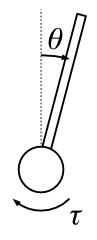

where $\theta$ is the pendulum angle, $\tau$ is the input torque, $m,l,J$ are the pendulm mass, length and inertia respectively.

The viscous firiction coefficient is given by $\mu \;$and the gravity acceleration is given by $g$.

Then, the dynamics of the system is written in the follows.


$$J\ddot{\theta}(t)+\mu\dot{\theta}(t)=mgl\sin\theta(t) + \tau$$


## TASK 1

- Rewrite the system in a state-space form. Assume the input is $\tau$ and the output is $\theta$.

- Discretize the system by sampling period 1 ms.

- Design a state feedback controller for the discritized system to be stable.

- Show the input/output responce of the stabilized system where the initial angle is $\theta =0\ldotp$5 [rad] and the initial angle speed is $\dot{\theta} =0$. (It means time series graphs of $\tau$ and $\theta \;$are needed.) 

#### NOTE:

- TASK 1 does NOT require step or impulse responses. So do not use the functions `step` or `impulse`.

- The handout shows only a pole assignment method but you can apply another method if you know. Do not choose the feedback gain directory with try and error.

- The input gets huge If you choose the closed loop poles as small values. You can get additional score if $|\tau |<100$ or $|\tau |<10$.

clear

%%%%%%%%%%%%%%%%%%%%%%%%
% Use the following variables for the system paremeters.
% Do not change these values.
m=0.107;
J=1.84*10e-3;
l=0.23;
g=9.8;
mu=2.56*10e-4;
%%%%%%%%%%%%%%%%%%%%%%%%

%% Write your code with referring Handout #3 %%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure(1)
subplot(2,1,1)
stairs(t,u1)
xlabel('Time [s]')
ylabel('$\tau$ [Nm]','Interpreter','latex')
subplot(2,1,2)
stairs(t,y1)
xlabel('Time [s]')
ylabel('$\theta$ [rad]','Interpreter','latex')


## TASK 2

In many cases, angle speeds are more difficult to measure than angles. State observers can solves this problem.

- Design a state observer to estimate the angle speed $\dot{\theta} \;$for the system.

- Show the input/output response using estimated states for feedback controller designed in TASK1. Also show the estimated states and the real state in a same graph for the comparison.

%% Write your code with referring Handout #3 %%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure(2)
subplot(2,1,1)
stairs(t,u2)
xlabel('Time [s]')
ylabel('$\tau$ [Nm]','Interpreter','latex')

subplot(2,1,2)
stairs(t,y2)
xlabel('Time [s]')
ylabel('$\theta$ [rad]','Interpreter','latex')

figure(3)
subplot(2,1,1)
stairs(t,x2(1,1:end-1))
hold on
stairs(t,q2(1,1:end-1))
% Tune the range to be easy to compare
%xlim([0 1]) 
%ylim([-1 1]) 
xlabel('Time [s]')
ylabel('$\theta$ [rad]','Interpreter','latex')
legend('True','Estimated')
hold off

subplot(2,1,2)
stairs(t,x2(2,1:end-1))
hold on
stairs(t,q2(2,1:end-1))
% Tune the range to be easy to compare
% Do not need to show to the end time of simulation
%xlim([0 1]) 
%ylim([-1 1]) 
xlabel('Time [s]')
ylabel('$\dot\theta$ [rad/s]','Interpreter','latex')
legend('True','Estimated')
hold off

## TASK 3

Quantization should be considered when low resolution acutuators/sensors or low capacity network are used in a system.

One of the quantization method, a $\Delta \Sigma$ modulator, is given by

$\left\{\begin{array}{l}
\xi[k+1]=\xi[k]+v[k]-u[k]\\
v[k]=q\left[-\xi[k]+u[k]\right]
\end{array}
\right.$.

- Simulate the system with input quantization by a $\Delta \Sigma$ modulator, where the quantization interval $d=2\ldotp$ (You can also choose a larger value. Output quantization is your option.)

- Show the input/output response of the quantized system. Also show the responce of the quantized system without a $\Delta \Sigma$ modulator ("simple static quantization" in the handout)

%% Write your code with referring Handout #5 %%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure(4)
subplot(2,1,1)
stairs(t,v3) % Input with a modulator
hold on
stairs(t,v4) % Input without a modulator
xlabel('Time [s]')
ylabel('$\tau$ [Nm]','Interpreter','latex')
legend('With modulator','Without modulator')
hold off

subplot(2,1,2)
stairs(t,y3) % Output with a modulator
hold on
stairs(t,y4) % Output without a modulator
xlabel('Time [s]')
ylabel('$\theta$ [rad]','Interpreter','latex')
legend('With modulator','Without modulator')
hold off
